# summarizeTestResult demo 1

This script shows how the `summarizeTestResult` function works. The function needs a proper test result XML file, which the Build Tool can generate.

Find an existing test result file.

test_result_file = SearchUtil1.searchFiles("sample-test-result.xml");
disp(test_result_file)

    "C:\local\modutil\modeling-utility\Devel\TestUtil\Test\summarizeTestResult\sample-test-result.xml"
    "C:\local\modutil\modeling-utility\Devel\TestUtil\sample-test-result.xml"



assert(not(isempty(test_result_file)))
test_result_file = test_result_file(1);

Run the function.

test_summary = TestUtil1.summarizeTestResult(test_result_file);

The summary table has custom properties.

num_tests = test_summary.Properties.CustomProperties.NumberOfTests;
disp("Number of tests: " + num_tests)

Number of tests: 38


disp("Total test time (seconds): " + test_summary.Properties.CustomProperties.TotalTestTimeInSeconds)

Total test time (seconds): 45.2956


median_test_time = test_summary.Properties.CustomProperties.MedianTestTimeInSeconds;
disp("Median test time (seconds): " + median_test_time)

Median test time (seconds): 0.062424


The table has the rows of test results sorted by test time.

disp(head(test_summary))

                TestClass                           TestFunction               TestTimeInSeconds
    __________________________________    _________________________________    _________________

    "uitest_SearchUtilApps"               "LightTheme_2"                             11.452     
    "uitest_SearchUtilApps"               "Gesture_1"                                10.899     
    "uitest_SearchUtilApps"               "LightTheme_1"                             9.2214     
    "uitest_SearchUtilApps"               "Gesture_2"                                 8.221     
    "uitest_SearchUtilApps"               "app_launches_without_warnings_1"          2.0012     
    "uitest_SearchUtilApps"               "app_launches_without_warnings_2"         0.81091     
    "unittest_buildReplaceCommandText"    "PassingTest_1"                           0.38494     
    "unittest_replaceTex

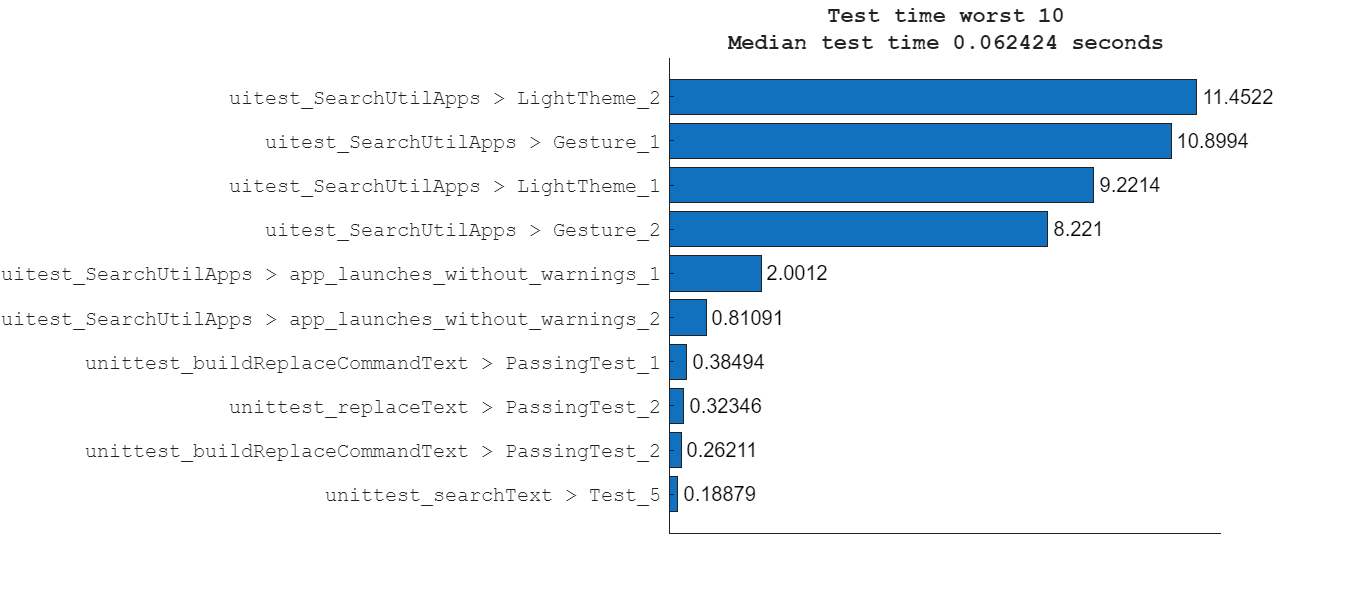

threshold = 10;
assert(threshold < num_tests)

test_fullname = test_summary.TestClass + " > " + test_summary.TestFunction;
testname = test_fullname(1:threshold);
testname = flip(testname);

testtime = test_summary.TestTimeInSeconds;
testtime = flip(testtime(1:threshold));

fig = figure;
fig.Position(3) = 900;  % width
fig.Position(4) = 400;  % height
ax = axes(fig);

b = barh(ax, testname, testtime);
b.Labels = b.YData;  % Show bar labels

ax.TickLabelInterpreter = "none";
ax.FontName = "FixedWidth";
ax.Box = "off";
% axis(ax, "off")

xticks(ax, [])

title(ax, ["Test time worst " + threshold; "Median test time " + median_test_time + " seconds"])

*Copyright 2025 The MathWorks, Inc.*